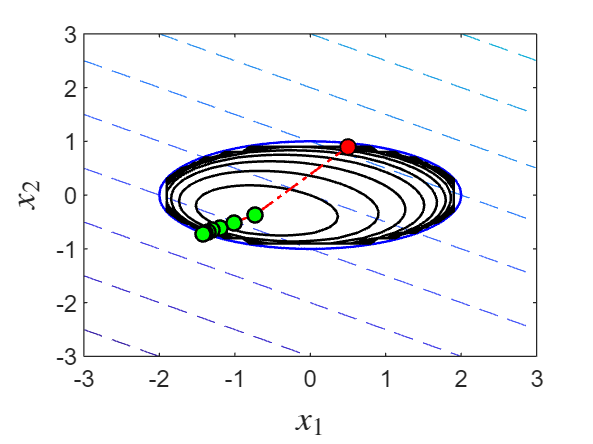

clear xs_P;
clf; clc;

f = @(x1, x2) x1 + 2*x2;
g = @(x1, x2) (1/4)*x1.^2 + x2.^2 - 1;
p = @(x1, x2) (g(x1, x2) < 0).*(-(log(-g(x1, x2)))) ... 
    + (g(x1, x2) >= 0 ).*1e200;
% use logic time the required result
Qb = @(x1, x2, mu) f(x1, x2) + mu*p(x1,x2);

gcb = @(x) sqrt(-(1/4)*x.^2 + 1);
f1 = @(x) x(1) + 2*x(2);
g1 = @(x) (1/4)*x(1).^2 + x(2).^2 - 1;
p1 = @(x, mu) (g1(x) < 0).*(-(log(-g1(x)))) + (g1(x) >= 0).*1e200;
Qb1 = @(x, mu) f1(x) + mu*p1(x);

% next step 
x1 = -3:0.1:3; x2 = -3:0.1:3;
x1s = -2:0.01:2; 
[X1, X2] = meshgrid(x1, x2);




% Initail values of all variables
x0 = [0.5, 0.9];
x01 = x0;
mu1 = 2;

% Contour plot of the objective function 
contour(X1, X2, f(X1, X2), LineStyle='--');

hold on
plot(x1s, gcb(x1s), linewidth=1, color='b');
plot(x1s, -gcb(x1s), linewidth=1, color='b');
levels = -30:1:30;
contour(X1, X2, Qb(X1, X2, mu1),levels , color='k', linewidth=1);

xlabel("$x_1$",'Interpreter','latex','FontSize',14);
ylabel("$x_2$",'Interpreter','latex','FontSize',14);

xerr = Inf ;

N = 100; xs_P = zeros(N, 2);
xs_P(1,:) = x0;
ii = 1;
rho = 0.5; 

while (norm(xerr) > 1e-10) && (ii < N)
    obj = @(x) f1(x) + (mu1)*p1(x);
    options = optimoptions(@fminunc,'Display','none');%,'maxiterations', 11);
    xr = fminunc(obj, x0, options);
    xs_P(ii+1,:) = xr;
    xerr = xr - x0;
    mu1 = rho*mu1;
    x0 = xr;
    ii = ii + 1;
end

%contour(X1, X2, Qb(X1, X2, mu1),levels , color='k', linewidth=1);
plot(xs_P(1:ii,1), xs_P(1:ii,2),'ro-.', 'MarkerFaceColor','g', ...
    'linewidth',1, 'MarkerEdgeColor','k')
plot(x01(1,1), x01(1,2),'ro','MarkerFaceColor','r','MarkerEdgeColor','k' )

hold off